% Define the range of 'a' values
a_values = linspace(1.9, 2.0, 11);
gamma_values = zeros(size(a_values));

for idx = 1:length(a_values)
    a = a_values(idx);

    % Define the system matrices for the given 'a'
    A1 = [0, 1, 0; -1e5, -1e2, 1; -a*5e6, 0, 0];
    A2 = [0, 1, 0; -1e5, -1e2, 1; -5e6, 0, 0];
    B = [0; 1; 0];

    % Create state-space systems
    sys1 = ss(A1, B, eye(3), zeros(3, 1));
    sys2 = ss(A2, B, eye(3), zeros(3, 1));

    % Obtain balanced realizations
    [sys1_bal, ~] = balreal(sys1);
    [sys2_bal, ~] = balreal(sys2);

    % Extract balanced system matrices
    A1_bal = sys1_bal.A;
    A2_bal = sys2_bal.A;
    B_bal = sys1_bal.B; % B is same for both systems

    % Define the LMI problem
    setlmis([]);
    P1 = lmivar(1, [3, 1]); % P1 is symmetric
    P2 = lmivar(1, [3, 1]); % P2 is symmetric
    gamma = lmivar(1, [1, 1]); % scalar gamma

    % LMI constraints for P1
    lmiterm([-1 1 1 P1], 1, 1); % P1 > 0
    lmiterm([-2 1 1 P1], A1_bal', 1, 's'); % A1_bal' * P1 + P1 * A1_bal
    lmiterm([-2 1 1 P1], 1, 1); % + Q1 (Q1 is identity for position x)
    lmiterm([-2 2 1 P1], B_bal', 1); % P1 * B
    lmiterm([-2 2 2 gamma], -1, 1); % -gamma^2 * I

    % LMI constraints for P2
    lmiterm([-3 1 1 P2], 1, 1); % P2 > 0
    lmiterm([-4 1 1 P2], A2_bal', 1, 's'); % A2_bal' * P2 + P2 * A2_bal
    lmiterm([-4 1 1 P2], 1, 1); % + Q2 (Q2 is identity for position x)
    lmiterm([-4 2 1 P2], B_bal', 1); % P2 * B
    lmiterm([-4 2 2 gamma], -1, 1); % -gamma^2 * I

    lmis = getlmis;

    % Solve the LMI problem
    [tmin, xfeas] = feasp(lmis);
    gamma_values(idx) = gamma;

end


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.023570
     2                        0.010552
     3                        0.010552
     4                    1.186225e-03
     5                    8.126413e-04
     6                    8.126413e-04
     7                    1.170726e-04
     8                    1.000049e-04
     9                    2.460392e-05
    10                    2.460392e-05
    11                    4.613263e-07
    12                    4.613263e-07
    13                    1.517884e-08
    14                    1.152949e-10
    15                    1.152949e-10
    16                    1.152949e-10
    17                    1.152949e-10
    18                    4.565707e-12
    19                    4.565707e-12
    20                    4.565707e-12
    21

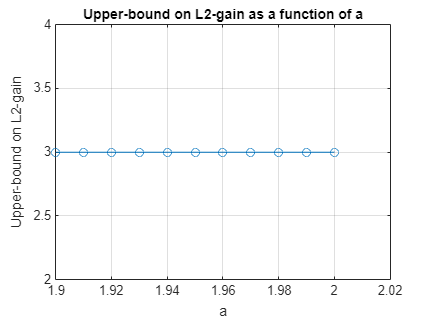


% Plot the results
plot(a_values, gamma_values, '-o');
xlabel('a');
ylabel('Upper-bound on L2-gain');
title('Upper-bound on L2-gain as a function of a');
grid on;